# 图1的代码

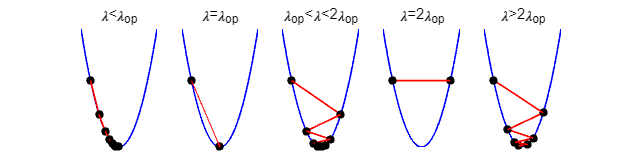

clc
clear

y=@(x) x.^2;
x='x';
x0(1)=-1.5;
epsilon=0.01;
r=0.3;
r1=1.7;
r2=2.4;
r3=2;
x6(1)=-0.2;


[x0,j] = GD(y,x,x0,epsilon);
[x2,j1] = GD(y,x,x0,epsilon,r);
[x3,j2] = GD(y,x,x0,epsilon,r1);
[x4,j3] = GD(y,x,x6,epsilon,r2);
[x5,j4] = GD(y,x,x0,epsilon,r3);

a=-2:0.01:2;
figure('Position',[700,700,1200,320],'Color','w')

subplot(151)
plot(a,y(a),'b','LineWidth',1)
ylim([0,4])
box off
% set(gca,'Visible','off');
set(gca,'xtick',[],'ytick',[],'XColor','w','YColor','w') % 隐藏x,y轴坐标
hold on
y2=y(x2);
[x1,y1,u,v]=jt(x2,y2);
for i =1:j1-1
    plot(x2(i),y2(i),'k.','MarkerSize',15)
    quiver(x1(i),y1(i),u(i),v(i),1,'r',"filled","LineWidth",1)
end
plot(x2(j1),y2(j1),'k.','MarkerSize',15)
title('\lambda<\lambda_{op}')

subplot(152)
plot(a,y(a),'b','LineWidth',1)
ylim([0,4])
box off
% set(gca,'Visible','off');
set(gca,'xtick',[],'ytick',[],'XColor','w','YColor','w') % 隐藏x,y轴坐标
hold on
for i =1:j
    plot(x0(i),y(x0(i)),'k.','MarkerSize',15)
end
y0=y(x0);
[x1,y1,u,v]=jt(x0,y0);
quiver(x1,y1,u,v,1,'r',"filled")
title('\lambda=\lambda_{op}')

subplot(153)
plot(a,y(a),'b','LineWidth',1)
ylim([0,4])
box off
% set(gca,'Visible','off');
set(gca,'xtick',[],'ytick',[],'XColor','w','YColor','w') % 隐藏x,y轴坐标
hold on
y3=y(x3);
[x1,y1,u,v]=jt(x3,y3);
for i =1:j2-1
    plot(x3(i),y3(i),'k.','MarkerSize',15)
    quiver(x1(i),y1(i),u(i),v(i),1,'r',"filled","LineWidth",1)
end
plot(x3(j2),y3(j2),'k.','MarkerSize',15)
title('\lambda_{op}<\lambda<2\lambda_{op}')

subplot(154)
plot(a,y(a),'b','LineWidth',1)
ylim([0,4])
box off
% set(gca,'Visible','off');
set(gca,'xtick',[],'ytick',[],'XColor','w','YColor','w') % 隐藏x,y轴坐标
hold on
y5=y(x5);
[x1,y1,u,v]=jt(x5,y5);
for i =1:j4-1
    plot(x5(i),y5(i),'k.','MarkerSize',15)
    quiver(x1(i),y1(i),u(i),v(i),1,'r',"filled","LineWidth",1)
end
plot(x5(j4),y5(j4),'k.','MarkerSize',15)
title('\lambda=2\lambda_{op}')

subplot(155)
plot(a,y(a),'b','LineWidth',1)
ylim([0,4])
box off
% set(gca,'Visible','off');
set(gca,'xtick',[],'ytick',[],'XColor','w','YColor','w') % 隐藏x,y轴坐标
hold on
y4=y(x4);
[x1,y1,u,v]=jt(x4,y4);
for i =1:j3-1
    plot(x4(i),y4(i),'k.','MarkerSize',15)
    quiver(x1(i),y1(i),u(i),v(i),1,'r',"filled","LineWidth",1)
end
plot(x4(j3),y4(j3),'k.','MarkerSize',15)
title('\lambda>2\lambda_{op}')

function [x0,i] = GD(f,x,x0,epsilon,varargin)
% 梯度下降法 也可以称：最速下降法
% output：x0 为GD函数出来的从起始点x0寻优到极小值点的所有点集合
%        i 为GD函数寻优过程得到点的个数即：i==length(x0)
%        可以打印出最小值 min{f}，以及极小值值点 x
% @Author     
% Copyright© 2022.5.22 CSDN name: cugautozp
i=1;
df = nabla_f(f,x);
H = Hesse(df,x);
dfx=df(x0(1));

if ~isempty(varargin)
    r=varargin{1};
end

er=norm(dfx);
while er > epsilon
    p = -dfx;
    lambda = dfx'*dfx/(dfx'*H*dfx);
    i=i+1;
    if isempty(varargin)
        x0(i) = x0(i-1)+lambda*p;
    else
        x0(i) = x0(i-1)+r*lambda*p;
        if r>2 && abs(x0(i))>1.5
            break
        elseif r==2 && i>4
            break
        end
    end

    dfx = df(x0(i));
    er = norm(dfx);
end
%     fmin = f(x0{i}(1),x0{i}(2));
%     disp('极小值点：');
%     disp(['x1 = ',num2str(x0{i}(1))]);
%     disp(['x2 = ',num2str(x0{i}(2))]);
%     fprintf('\nf最小值：\n min{f}=%f\n',fmin);
end

function [x0,i] = GD1(f,x,x0,epsilon,r)
% 梯度下降法 也可以称：最速下降法
% output：x0 为GD函数出来的从起始点x0寻优到极小值点的所有点集合
%        i 为GD函数寻优过程得到点的个数即：i==length(x0)
%        可以打印出最小值 min{f}，以及极小值值点 x
%

i=1;
df = nabla_f(f,x);
H = Hesse(df,x);
dfx=df(x0(1));

er=norm(dfx);
while er > epsilon
    p = -dfx;
    lambda = dfx'*dfx/(dfx'*H*dfx);
    i=i+1;
    x0(i) = x0(i-1)+r*lambda*p;
    dfx = df(x0(i));
    er = norm(dfx);
    if r>2 && abs(x0(i))>1.5
        break
    elseif r==2 && i>4
        break
    end
end
%     fmin = f(x0{i}(1),x0{i}(2));
%     disp('极小值点：');
%     disp(['x1 = ',num2str(x0{i}(1))]);
%     disp(['x2 = ',num2str(x0{i}(2))]);
%     fprintf('\nf最小值：\n min{f}=%f\n',fmin);
end

function df=nabla_f(fun,x)
%  ∇f 求梯度
df=[];
x=str2sym(x);
for i=1:length(x)
    df1 = diff(fun,x(i));
    df=[df;df1];
end
df= matlabFunction(df);
end

function H = Hesse(df,x)
%  Hesse矩阵 H(x)=∇(∇f)
%  df 为 ∇f，即为函数nabla_f的结果 ∇f
H=[];
x=str2sym(x);
for i=1:length(x)
    df1 = diff(df,x(i));
    H=[H,df1];
end
H=double(H);
end


function [x,y,u,v]=jt(x,y)
u = diff(x)';
v = diff(y)';
x(length(x))=[];
y(length(y))=[];
x=x';
y=y';
end